% Load the pre-trained model
load Neural_Networks\1-sign\resnet_18\resnet.mat

% Load the test dataset
signds = imageDatastore("D:\college\FYP\Dataset\Experimenting\test\no-parking", "IncludeSubfolders", true, "LabelSource", "foldernames");

% Split the dataset into training and testing sets
[signTrain, signTest] = splitEachLabel(signds, 0.8, "randomized");

% Augmentation
resizeTrainImgs = augmentedImageDatastore([224 224], signTrain);
resizeTestImgs = augmentedImageDatastore([224 224], signTest);

% Set the number of classes
numClasses = numel(categories(signds.Labels));

% Set training options
opts = trainingOptions("sgdm", "InitialLearnRate", 0.001, "MaxEpochs", 5, "VerboseFrequency", 1);

% Train the network
[Network1, info] = trainNetwork(resizeTrainImgs, resnet, opts);

Training on single CPU.
Initializing input data normalization.
|========================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Mini-batch  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |     Loss     |      Rate       |
|========================================================================================|
|       1 |           1 |       00:00:28 |       61.00% |       0.8914 |          0.0010 |
|       2 |           2 |       00:00:54 |       64.00% |       0.7777 |          0.0010 |
|       3 |           3 |       00:01:25 |       73.00% |       0.5942 |          0.0010 |
|       4 |           4 |       00:01:59 |       82.00% |       0.4064 |          0.0010 |
|       5 |           5 |       00:02:34 |       91.00% |       0.2676 |          0.0010 |
|========================================================================================|
Training finished: Max epoc

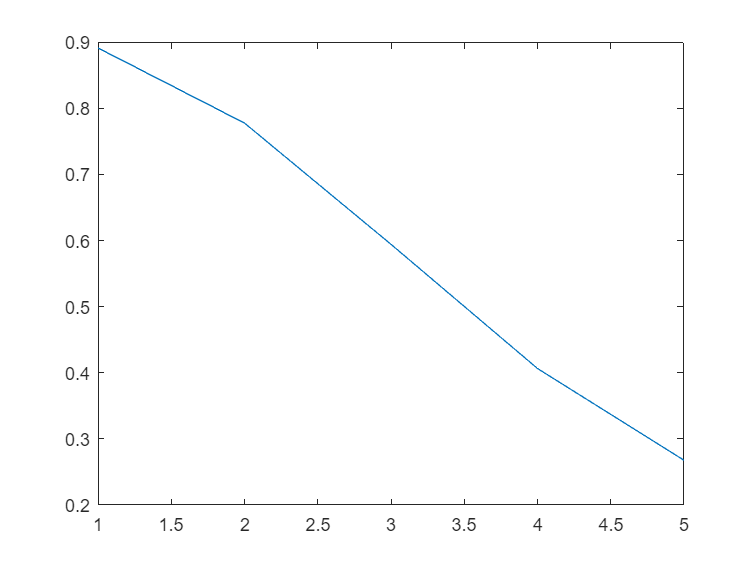


% Plot training loss
plot(info.TrainingLoss);


% Save the "signTest" dataset in respective folders
outputTestFolder = "D:\college\FYP\test_images\output"; % Change this path as per your requirement

for i = 1:numel(signTest.Files)
    imgPath = signTest.Files{i};
    [~, imgName, imgExt] = fileparts(imgPath);
    imgLabel = char(signTest.Labels(i));
    outputFolder = fullfile(outputTestFolder, imgLabel);
    
    % Create the class label folder if it doesn't exist
    if ~exist(outputFolder, 'dir')
        mkdir(outputFolder);
    end
    
    % Move the image to the respective folder
    outputImgPath = fullfile(outputFolder, strcat(imgName, imgExt));
    copyfile(imgPath, outputImgPath);
end

% Evaluate Performance
signPrediction = classify(Network1, resizeTestImgs);
signActual = signTest.Labels;

% Calculate accuracy
numCorrect = nnz(signPrediction == signActual);
fracCorrect = numCorrect / numel(signPrediction);

% Display accuracy
fprintf("Accuracy: %.2f%%\n", fracCorrect * 100);

Accuracy: 84.62%


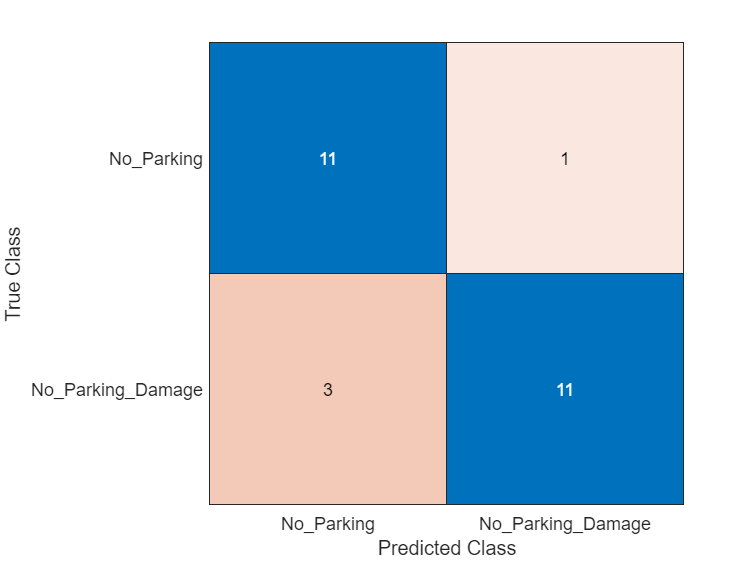


% Confusion Chart
confusionchart(signActual, signPrediction);